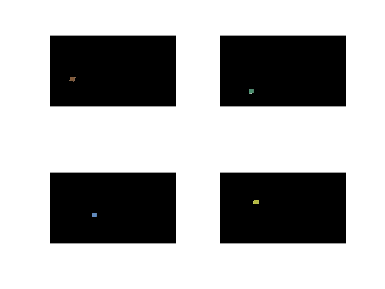

blocks = imread("blocks.jpeg");

r = blocks(:, :, 1);
g = blocks(:, :, 2);
b = blocks(:, :, 3);

% imshow(blocks);
% improfile();

redMask = r - g > 20 & r - b > 40;
blueMask = b - g > 30 & b - r > 60;
yellowMask = r - b > 80 & g - b > 80;
greenMask = g - b > 10 & g - r > 20;

redBlock = imoverlay(blocks, ~redMask, 'k');
greenBlock = imoverlay(blocks, ~greenMask, 'k');
blueBlock = imoverlay(blocks, ~blueMask, 'k');
yellowBlock = imoverlay(blocks, ~yellowMask, 'k');


subplot 221
imshow(redBlock)
subplot 222
imshow(greenBlock)
subplot 223
imshow(blueBlock)
subplot 224
imshow(yellowBlock)

gray_image_red=rgb2gray(redBlock)

gray_image_red = 899×1599 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

edges_red= edge(gray_image_red,"canny")

edges_red = 899×1599 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

corners_red= detectMinEigenFeatures(gray_image_red)

corners_red =   34×1 cornerPoints array with properties:

    Location: [34×2 single]
      Metric: [34×1 single]
       Count: 34


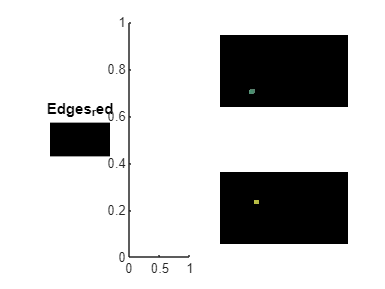

subplot(1, 4, 1);

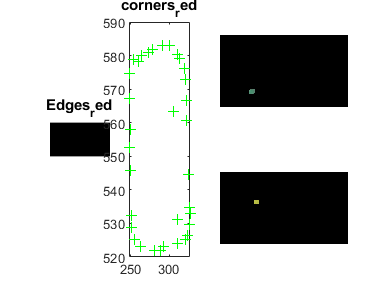

imshow(edges_red);
title('Edges_red');
subplot(1,4,2);
plot(corners_red)
title('corners_red')



gray_image_red=rgb2gray(redBlock)
edges_red= edge(gray_image_red,"canny")
corners_red= detectHarrisFeatures(gray_image_red)
subplot(1, 4, 1);
imshow(edges_red);
title('Edges_red');

gray_image_blue=rgb2gray(blueBlock)
edges_blue= edge(gray_image_blue,"canny")
subplot(1, 4, 2);
imshow(edges_blue);
title('Edges_blue');

gray_image_yellow=rgb2gray(yellowBlock)
edges_yellow= edge(gray_image_yellow,"canny")
subplot(1, 4, 3);
imshow(edges_yellow);
title('Edges_yellow');

gray_image_green=rgb2gray(greenBlock)
edges_green= edge(gray_image_green,"canny")
subplot(1, 4, 4);
imshow(edges_green);
title('Edges_green');

% edges_red = edge(redBlock,"canny");
% edges_blue = edge(blueBlock,"canny");
% edges_green = edge(greenBlock,"canny");
% edges_yellow = edge(yellowBlock,"canny");
% 
% subplot 221
% imshow(edges_red)
% subplot 222
% imshow(edges_blue)
% subplot 223
% imshow(edges_green)
% subplot 224
% imshow(edges_yellow)

% imshowpair(redMask, blueMask, "montage");

% Get the size of the image
[rows, columns, channels] = size(blocks);

% Calculate the depth
if channels == 1
    depth = 8; % Grayscale image
elseif channels == 3
    depth = 24; % RGB color image
elseif channels == 4
    depth = 32; % RGBA color image
else
    depth = NaN; % Unsupported image format
end

% Display the depth
fprintf('Image depth: %d bits per pixel\n', depth);